# Sistemas Realimentados - 2023/2

## Nome: Gabrielly Barcelos Cariman

## Data limite para entrega: 4/10, 6h da manhã.

## Trabalho 3 - Projeto de controladores PID via método do lugar das raízes.

I=14; % Seu valor de I
[G1,G2,G3, iae_G1, iae_G3, ts_G2]=ini_t3(I);
datetime('now')

ans = datetime
   04-Oct-2023 03:27:16


**Atividade 1: Projeto de um controlador PI para sistema de primeira ordem + tempo morto (G1(s)). **

Projetar um controlador PI via método do lugar das raízes usando a FT G1. O controlador resultante C1 deve resultar em um valor de $IAE\leq iae_{G1}$ e erro nulo para entrada degrau.

Mostrar o controlador e o LR utilizado, explicar as escolhas da localização do zero do controlador para atender a especificação e a obtenção de Kp e Ki do LR.

G1

G1 =
 
                  8
  exp(-10*s) * --------
               40 s + 1
 
Continuous-time transfer function.
Model Properties


iae_G1

iae_G1 = 22.3904

Como o sistema possui tempo morto, a aproximação de Pade deve ser utilizada no projeto.

Vou optar pela aproximação de Pade de ordem 1 para adicionar a menor complexidade possível ao LR.

G1_pade = pade(G1,1)

G1_pade =
 
      -8 s + 1.6
  ------------------
  40 s^2 + 9 s + 0.2
 
Continuous-time transfer function.
Model Properties


A FT do controlador PI é dado por:


$$C(s) = K_p \frac{\left ( s+\frac{K_i}{K_p} \right )}{s}$$


O projeto do PI via LR envolve:

- Adicionar um polo na origem; 

- Escolher a localização do zero;

- Definir o ganho $K_p$;

- Calcular o ganho $K_i$.

Vamos `fazer esses passos:`

Adicionar um polo na origem:

s=tf('s');
G1_pade_polo = G1_pade * 1/s

G1_pade_polo =
 
        -8 s + 1.6
  ----------------------
  40 s^3 + 9 s^2 + 0.2 s
 
Continuous-time transfer function.
Model Properties


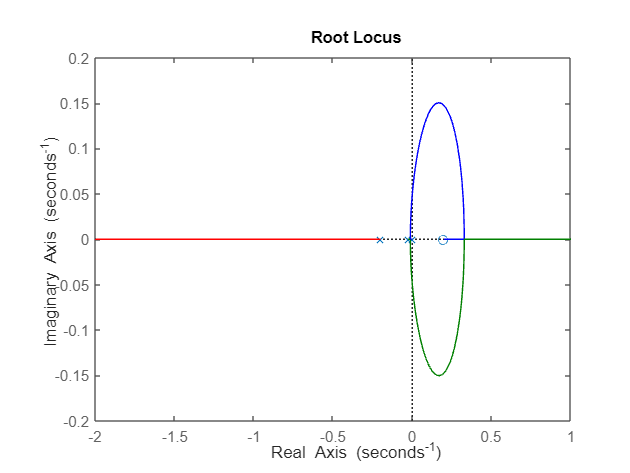

rlocus(G1_pade_polo)

Escolher a localização do zero:

G1_pade

G1_pade =
 
      -8 s + 1.6
  ------------------
  40 s^2 + 9 s + 0.2
 
Continuous-time transfer function.
Model Properties


G1_pade(s) = $\frac{-8s +1.6}{40s^2+9s+0.2}$ = $\frac{-8s + 1.6}{(s+0.025)(s+0.2)}$

Uma abordagem inicial que pode proporcionar bons resultados seria executar um procedimento semelhante ao método de síntese direta. 

Para simular um pouco do procedimento realizado no método de síntese direta, precisamos que o zero de PI anule um polo de G1(s). 

Portanto, inicialmente, vamos posicionar o zero de PI em -0.025 para que ele anule o polo em -0.025 de G1(s).

Vamos analisar o resultado dessa modificação:

G1_pade_polo_zero = G1_pade_polo*(s+0.025)

G1_pade_polo_zero =
 
  -8 s^2 + 1.4 s + 0.04
  ----------------------
  40 s^3 + 9 s^2 + 0.2 s
 
Continuous-time transfer function.
Model Properties


%rltool(G1_pade_polo_zero)

Ao posicionar o zero de PI em -0.025, anulamos o polo em -0.025 de G1(s).

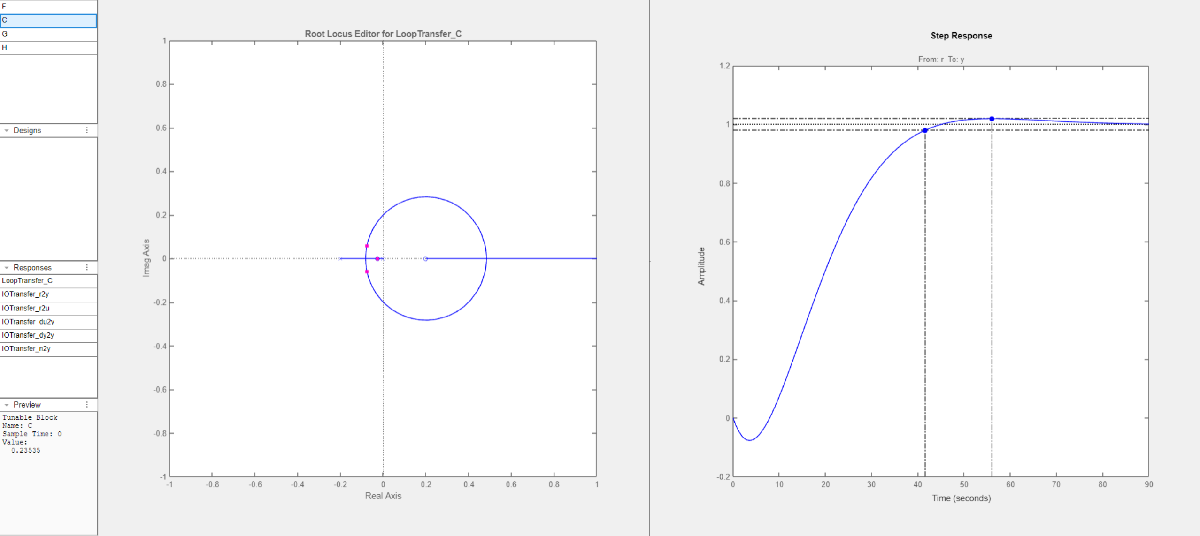

É possível observar no gráfico acima que essa ótima resposta foi obtida para o zero em -0.025 e um ganho de 0.23535. 

Essa resposta possui uma sobressinal de 1.74%, e o seu tempo de estabilização é 42.4 segundos.

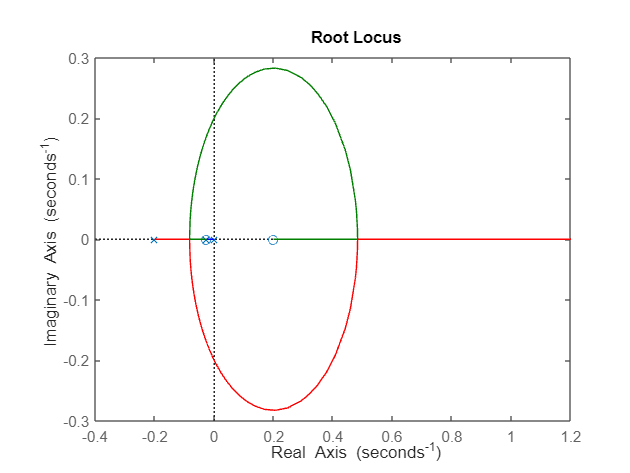

rlocus(G1_pade_polo_zero)

A FT do controlador PI é dado por:


$$C(s) = K_p \frac{\left ( s+\frac{K_i}{K_p} \right )}{s}$$


Logo, temos que $K_p =\;$ganho. 

Como o zero é em -0.025. Temos:


$$\frac{K_i}{K_p} = 0.025$$



$$K_i =0\ldotp 025K_p$$


Kp = 0.23535

Kp = 0.2354

Ki_sobre_Kp = 0.025;
Ki = Ki_sobre_Kp*Kp

Ki = 0.0059

C1 = Kp *((s+Ki_sobre_Kp)/s)

C1 =
 
  0.2354 s + 0.005884
  -------------------
           s
 
Continuous-time transfer function.
Model Properties


Apresentação do resultado: simulação e o cálculo do IAE usando o controlador C1 projetado.

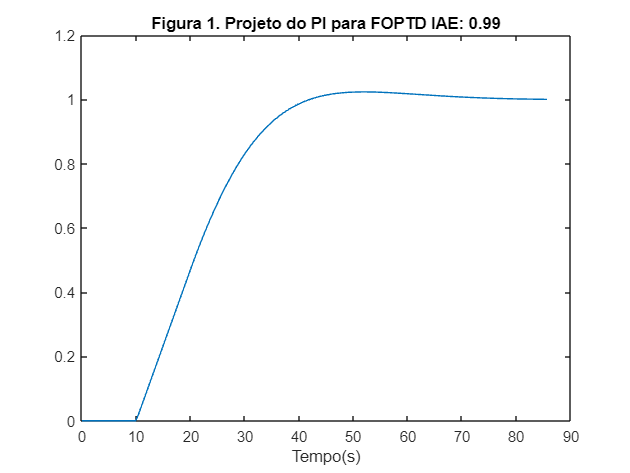

M1=feedback(C1*G1,1);
[y,t]=step(M1);
t=linspace(0,max(t),200);
y=step(M1,t);
plot(t,y);xlabel('Tempo(s)');
iae1=trapz(t,abs(1-y));
ss=sprintf('Figura 1. Projeto do PI para FOPTD IAE: %3.2f', iae1/iae_G1);
title(ss);

iae1

iae1 = 22.2451

iae_G1

iae_G1 = 22.3904

erro = 1-y(end)

erro = -1.8054e-04

O gráfico acima comprova que o controlador resultante C1 atendeu a todas as especificações e obteve um valor de $IAE\leq iae_{G1}$, $22.2451\leq 22.3904$, e erro nulo para uma entrada de degrau.

**Atividade 2: Projeto de um controlador C2  tipo PD via método do LR para o modelo de ordem 2 G2(s) que permita obter o  tempo de estabilização **$ts\leq ts_{G2}$** e com sobreelevação menor que 1%.**

Mostrar o controlador e o LR utilizado, explicar as escolhas da localização do zero do controlador para atender a especificação e a obtenção de Kp e Kd do LR.

G2

G2 =
 
           14
  --------------------
  s^3 + 45 s^2 + 200 s
 
Continuous-time transfer function.
Model Properties


ts_G2

ts_G2 = 0.2917

G2(s) = $\frac{14}{s^3+45s^2+200s}$ = $\frac{14}{s(s+5)(s+40)}$

Uma abordagem inicial que pode proporcionar bons resultados seria executar um procedimento semelhante ao método de síntese direta. 

Para simular um pouco do procedimento realizado no método de síntese direta, precisamos que o zero de PD anule um polo de G2(s). 

Portanto, inicialmente, vamos posicionar o zero de PD na origem para que ele anule o polo da origem de G2(s).

Ao fazer isso, é possível transformar o denominador de G2(s), que era um polinômio de terceiro grau, em um polinômio de segundo grau. 

Vamos analisar o resultado dessa modificação:

s=tf('s');
G2_zero = G2*s

G2_zero =
 
          14 s
  --------------------
  s^3 + 45 s^2 + 200 s
 
Continuous-time transfer function.
Model Properties


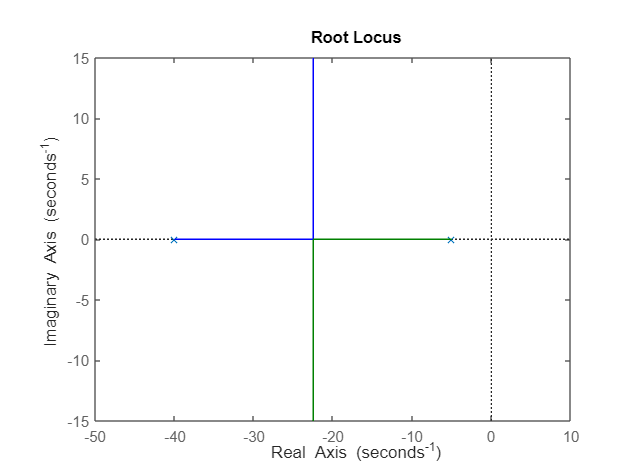

rlocus(G2_zero)

%rltool(G2)

Ao posicionar o zero de PD na origem, anulamos o polo de origem de G2(s).

Com isso, transformamos o denominador de G2(s) em um polinômio de segundo grau. 

Agora, é possível marcar no gráfico da resposta apenas as áreas em branco que apresentam um ganho que mantém a especificação correta:

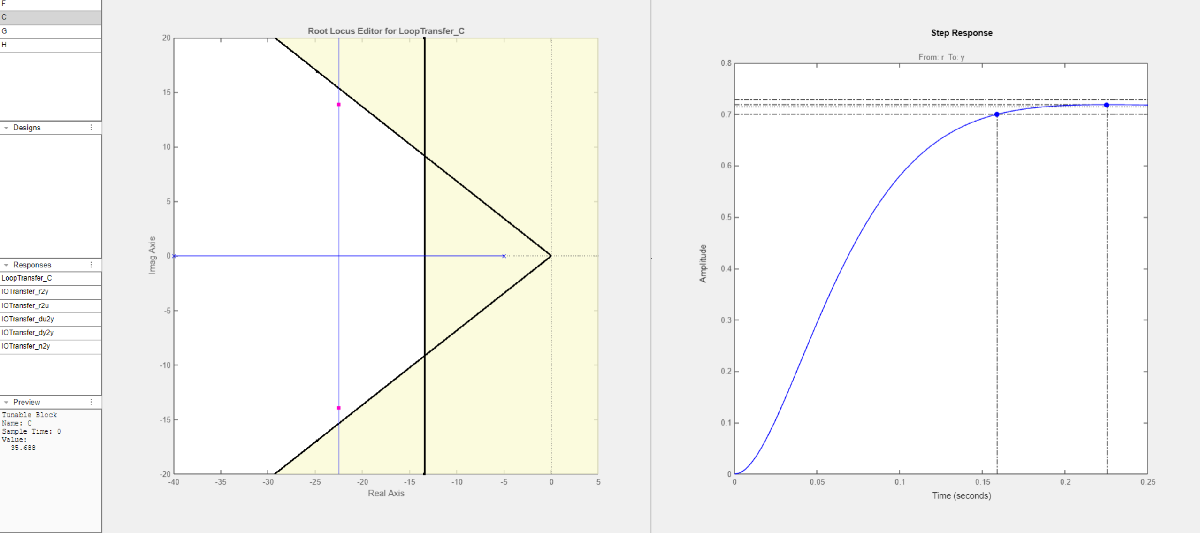

É possível observar no gráfico acima que essa ótima resposta foi obtida para o zero na origem e um ganho de 35.688. 

Essa resposta possui uma sobressinal de 0.62%, e o seu tempo de estabilização, de aproximadamente 0.15 segundos, atendendo a todas as especificações.

G2_zero_ganho = 35.688*G2_zero

G2_zero_ganho =
 
        499.6 s
  --------------------
  s^3 + 45 s^2 + 200 s
 
Continuous-time transfer function.
Model Properties


rlocus(G2_zero_ganho)

A FT do controlador PD é dado por:


$$C(s) = K_p + K_d s$$


Obtivemos a resposta acima ao multiplicar G2(s) por s (zero na origem) e, posteriormente, pelo ganho de 35.688.

Portanto, podemos identificar o controlador que multiplicou G2(s) como:


$$C\left(s\right)=35\ldotp 688*s$$


Comparando com a primeira equção apresentada do PD, temos que:


$$K_p =0$$



$$K_d =35\ldotp 688\;$$


Kp = 0

Kp = 0

Kd =35.688

Kd = 35.6880

C2 = Kp + Kd*s

C2 =
 
  35.69 s
 
Continuous-time transfer function.
Model Properties


Abaixo a simulação com o controlador C2 projetado.

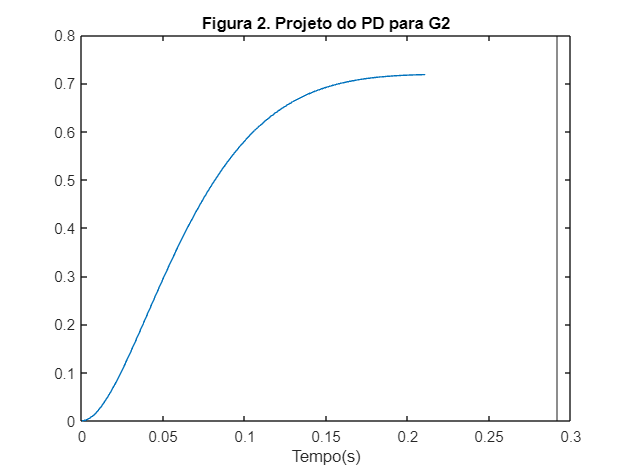

M2=feedback(C2*G2,1);
[y,t]=step(M2);
t=linspace(0,max(t),200);
y=step(M2,t);
plot(t,y);xline(ts_G2);
xlabel('Tempo(s)');title('Figura 2. Projeto do PD para G2')

S = stepinfo(M2);
up = S.Overshoot

up = 0.6200

ts = S.SettlingTime

ts = 0.1586

ts_G2

ts_G2 = 0.2917

A partir do exposto, podemos constatar que o controlador C2 atendeu a todas as especificações, obtendo um valor de $ts\leq ts_{G2}$, $0.1586\leq 0.2917$, e sobreelevação de 0.62%, menor que 1%.

**Atividade 3: Projeto de um controlador C3 PI ou PID para o modelo de ordem 4 G3(s) tal que se tenha **$IAE\leq iae_{G3}$.

Mostrar o(s) LR utilizado(s), explicar as escolhas para obter o controlador e atender a especificação e a obtenção dos ganhos do PID no LR.

G3

G3 =
 
                   1200
  ---------------------------------------
  s^4 + 40 s^3 + 600 s^2 + 4000 s + 10000
 
Continuous-time transfer function.
Model Properties


iae_G3

iae_G3 = 0.3663

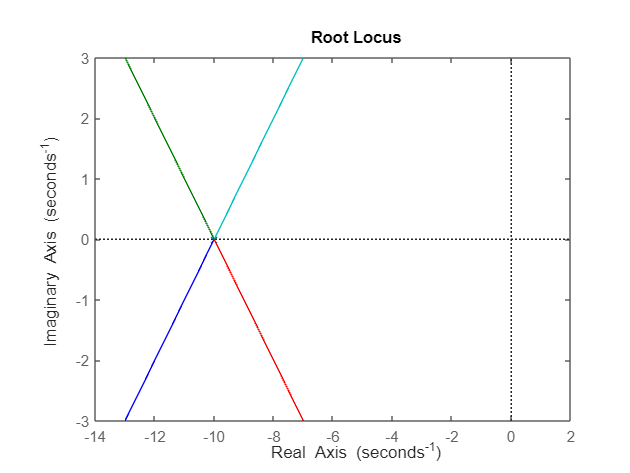

rlocus(G3)

- **Primeira tentativa de obter o controle:**

Vamos começar projetando um PI:

A FT do controlador PI é dado por:


$$C(s) = K_p \frac{\left ( s+\frac{K_i}{K_p} \right )}{s}$$


O projeto do PI via LR envolve:

- Adicionar um polo na origem; 

- Escolher a localização do zero;

- Definir o ganho $K_p$;

- Calcular o ganho $K_i$.

Vamos `fazer esses passos:`

Adicionar um polo na origem:

s=tf('s');
G3_polo = G3 * 1/s

G3_polo =
 
                     1200
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


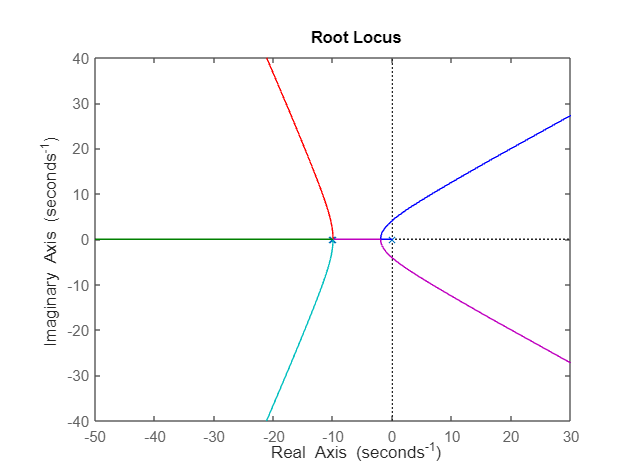

rlocus(G3_polo)

Escolher a localização do zero:

G3

G3 =
 
                   1200
  ---------------------------------------
  s^4 + 40 s^3 + 600 s^2 + 4000 s + 10000
 
Continuous-time transfer function.
Model Properties


G3(s) = $\frac{1200}{s^4+40s^3+600s^2+4000s+10000}$ = $\frac{1200}{(s+10)^4}$

Uma abordagem inicial que pode proporcionar bons resultados seria executar um procedimento semelhante ao método de síntese direta. 

Para simular um pouco do procedimento realizado no método de síntese direta, precisamos que o zero de PI anule um polo de G3(s). 

Portanto, inicialmente, vamos posicionar o zero de PI em -10 para que ele anule o polo em -10 de G3(s).

Vamos analisar o resultado dessa modificação:

G3_polo_zero = G3_polo*(s+5.25)

G3_polo_zero =
 
                 1200 s + 6300
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


G3_polo_zero = G3_polo*(s+10)

G3_polo_zero =
 
                1200 s + 12000
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


%rltool(G3_polo)

Ao posicionar o zero de PI em -10, anulamos o polo em -10 de G3(s).

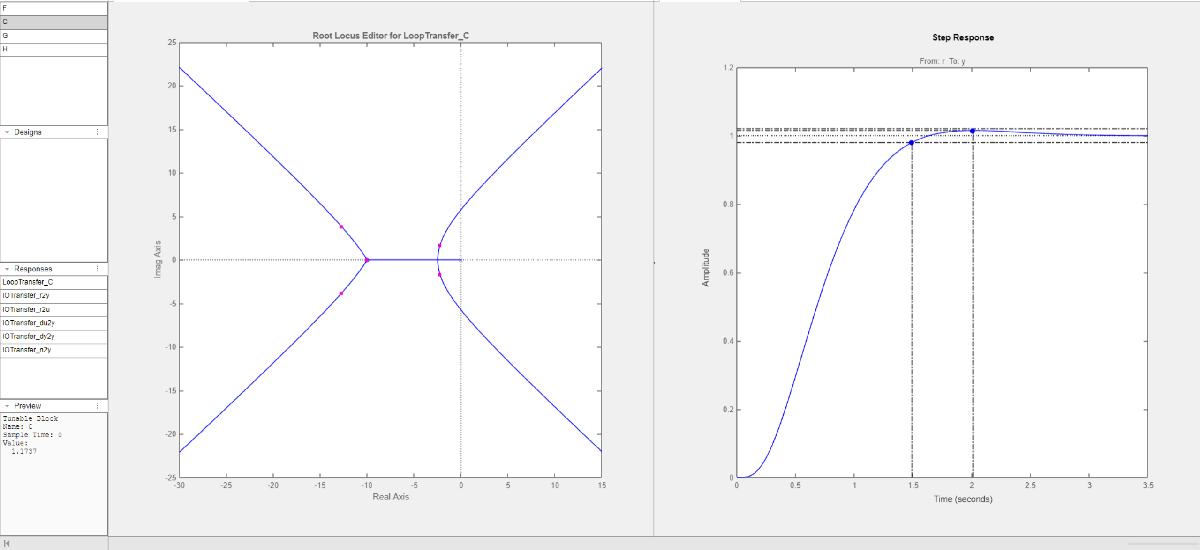

É possível observar no gráfico acima que essa resposta foi obtida para o zero em -10 e um ganho de 1.1737. 

Essa resposta possui uma sobressinal de 1.5%, e o seu tempo de estabilização é 1.49 segundos.

G3_polo_zero_ganho = G3_polo_zero*1.1737

G3_polo_zero_ganho =
 
               1408 s + 1.408e04
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


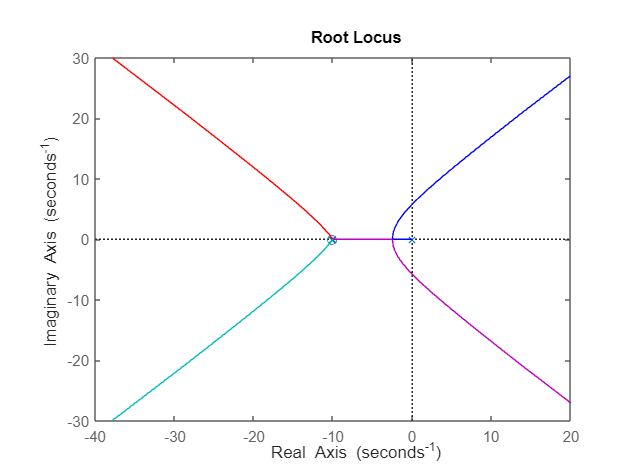

rlocus(G3_polo_zero_ganho)

A FT do controlador PI é dado por:


$$C(s) = K_p \frac{\left ( s+\frac{K_i}{K_p} \right )}{s}$$


Logo, temos que $K_p =\;$ganho. 

Como o zero é em -10. Temos:


$$\frac{K_i}{K_p} = 10$$



$$K_i =10K_p$$


Kp = 1.1737

Kp = 1.1737

Ki_sobre_Kp = 10;
Ki = Ki_sobre_Kp*Kp

Ki = 11.7370

C3 = Kp *((s+Ki_sobre_Kp)/s)

C3 =
 
  1.174 s + 11.74
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


Abaixo a simulação e o cálculo do IAE usando o controlador C3 projetado.

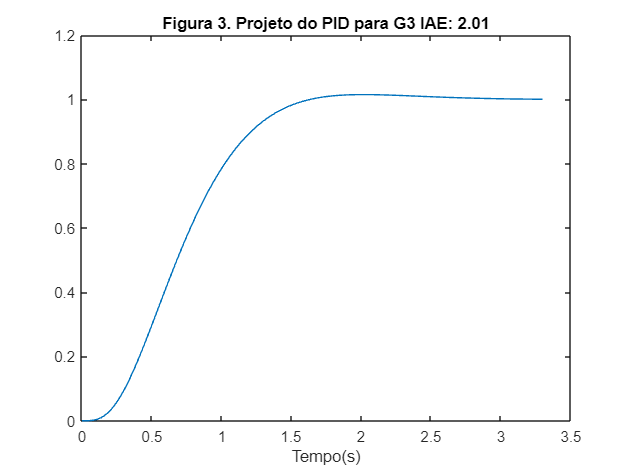

M3=feedback(C3*G3,1);
[y,t]=step(M3);
t=linspace(0,max(t),200);
y=step(M3,t);
plot(t,y);xlabel('Tempo(s)');
iae3=trapz(t,abs(1-y));
ss=sprintf('Figura 3. Projeto do PID para G3 IAE: %3.2f', iae3/iae_G3);
title(ss);

Mas essa resposta apenas com esse PI não conseguiu atender ao quer era pedido:

iae3

iae3 = 0.7352

iae_G3

iae_G3 = 0.3663

Vamos modelar um PD agora para construir o PID:

Uma abordagem inicial que pode proporcionar bons resultados seria executar um procedimento semelhante ao método de síntese direta. 

Para simular um pouco do procedimento realizado no método de síntese direta, precisamos que o zero de PD anule um polo de G3(s). 

Portanto, inicialmente, vamos posicionar o zero de PD em -10 para que ele anule um polo em -10 de G3(s).

Vamos analisar o resultado dessa modificação:

s=tf('s');
G3_polo_zero_zero = G3_polo_zero_ganho*(s+10)

G3_polo_zero_zero =
 
        1408 s^2 + 2.817e04 s + 140844
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


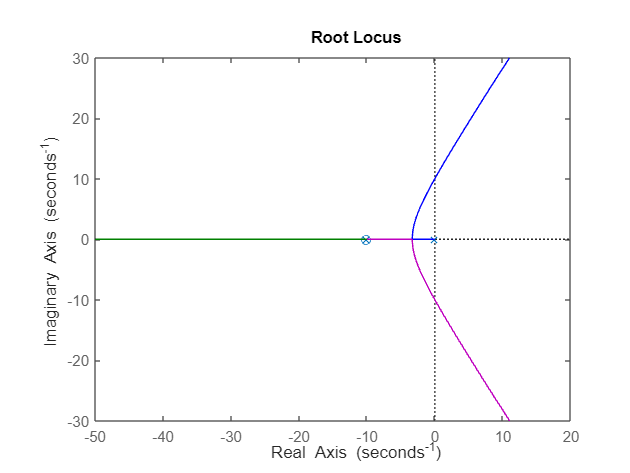

rlocus(G3_polo_zero_zero)

%rltool(G3_polo_zero_ganho)

Ao posicionar o zero de PD em -10, anulamos um polo em -10 de G3(s).

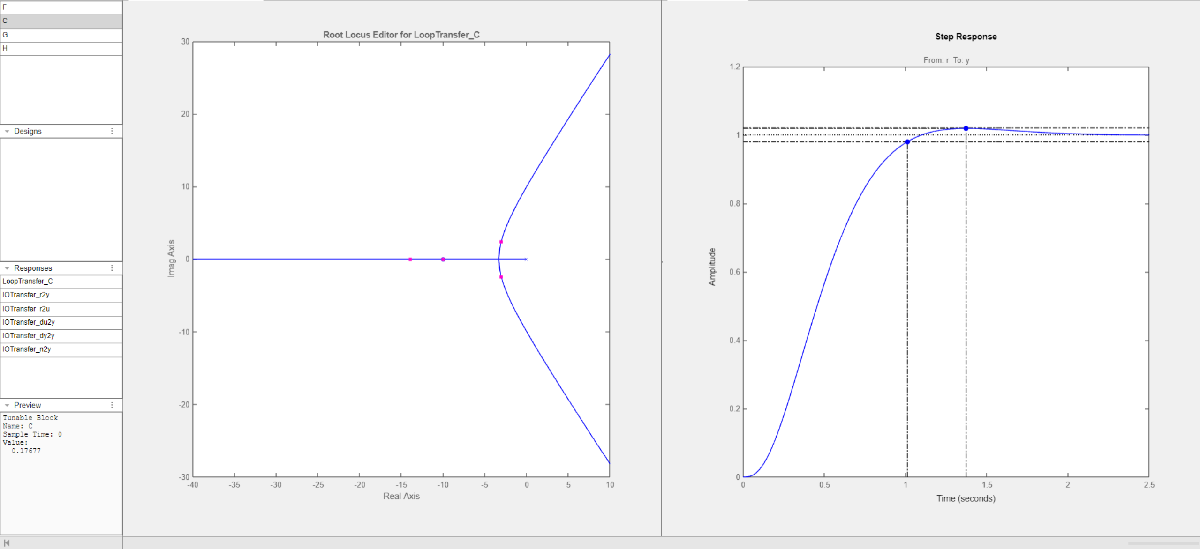

É possível observar no gráfico acima que essa resposta foi obtida para o zero em -10 e um ganho de 0.17677. 

Essa resposta possui uma sobressinal de 1.88%, e o seu tempo de estabilização, de aproximadamente 1.01 segundos.

G3_polo_zero_zero_ganho = 0.17677*G3_polo_zero_zero

G3_polo_zero_zero_ganho =
 
          249 s^2 + 4979 s + 2.49e04
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


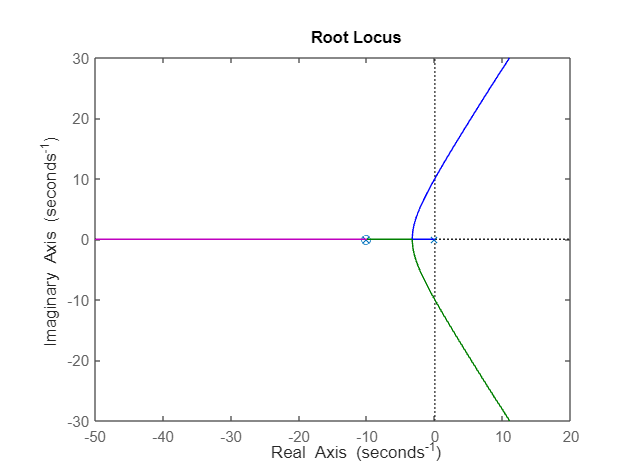

rlocus(G3_polo_zero_zero_ganho)

C3 = (1/s)*(s+10)*(s+10)*0.17677*1.1737

C3 =
 
  0.2075 s^2 + 4.149 s + 20.75
  ----------------------------
               s
 
Continuous-time transfer function.
Model Properties


Kd = 0.2075

Kd = 0.2075

Kp = 4.149

Kp = 4.1490

Ki = 20.75

Ki = 20.7500

Abaixo a simulação e o cálculo do IAE usando o controlador C3 projetado.

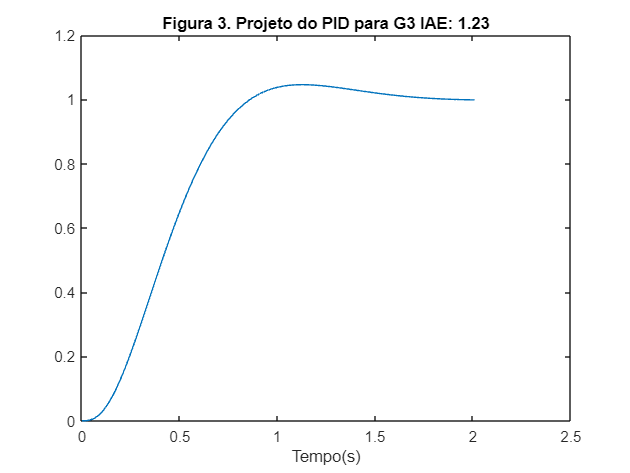

M3=feedback(C3*G3,1);
[y,t]=step(M3);
t=linspace(0,max(t),200);
y=step(M3,t);
plot(t,y);xlabel('Tempo(s)');
iae3=trapz(t,abs(1-y));
ss=sprintf('Figura 3. Projeto do PID para G3 IAE: %3.2f', iae3/iae_G3);
title(ss);

iae3

iae3 = 0.4504

iae_G3

iae_G3 = 0.3663

- **Segunda tentativa de obter o controle:**

Vamos usar apenas o rltool.

Vamos começar projetando um PI que tenha alto UP e seja rápido para o PD amortecer depois.

A FT do controlador PI é dado por:


$$C(s) = K_p \frac{\left ( s+\frac{K_i}{K_p} \right )}{s}$$


O projeto do PI via LR envolve:

- Adicionar um polo na origem; 

- Escolher a localização do zero;

- Definir o ganho $K_p$;

- Calcular o ganho $K_i$.

Vamos `fazer esses passos:`

Adicionar um polo na origem:

s=tf('s');
G3_polo = G3 * 1/s

G3_polo =
 
                     1200
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


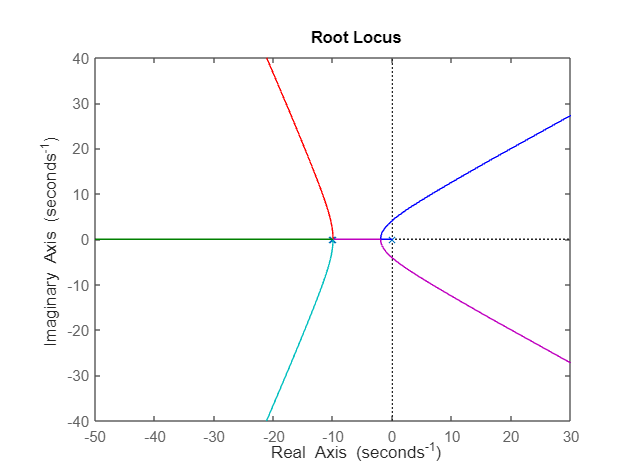

rlocus(G3_polo)

Escolher a localização do zero:

G3

G3 =
 
                   1200
  ---------------------------------------
  s^4 + 40 s^3 + 600 s^2 + 4000 s + 10000
 
Continuous-time transfer function.
Model Properties


G3(s) = $\frac{1200}{s^4+40s^3+600s^2+4000s+10000}$ = $\frac{1200}{(s+10)^4}$

Definição de um zero com alto UP:

G3_polo_zero = G3_polo*(s+5.25)

G3_polo_zero =
 
                 1200 s + 6300
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


%rltool(G3_polo)

É possível observar acima que essa resposta foi obtida para o zero em -5.25 e um ganho de 14.525. 

G3_polo_zero_ganho = G3_polo_zero*14.525

G3_polo_zero_ganho =
 
              17430 s + 9.151e04
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


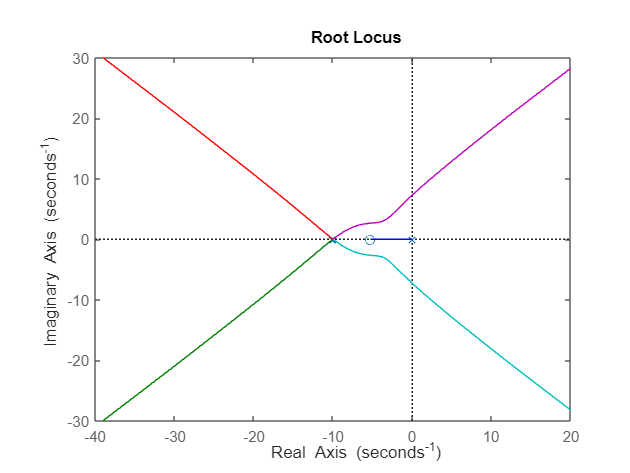

rlocus(G3_polo_zero_ganho)

A FT do controlador PI é dado por:


$$C(s) = K_p \frac{\left ( s+\frac{K_i}{K_p} \right )}{s}$$


Logo, temos que $K_p =\;$ganho. 

Como o zero é em -10. Temos:


$$\frac{K_i}{K_p} = 10$$



$$K_i =10K_p$$


Kp = 14.525

Kp = 14.5250

Ki_sobre_Kp = 5.25;
Ki = Ki_sobre_Kp*Kp

Ki = 76.2563

C3 = Kp *((s+Ki_sobre_Kp)/s)

C3 =
 
  14.53 s + 76.26
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


Abaixo a simulação e o cálculo do IAE usando o controlador C3 projetado.

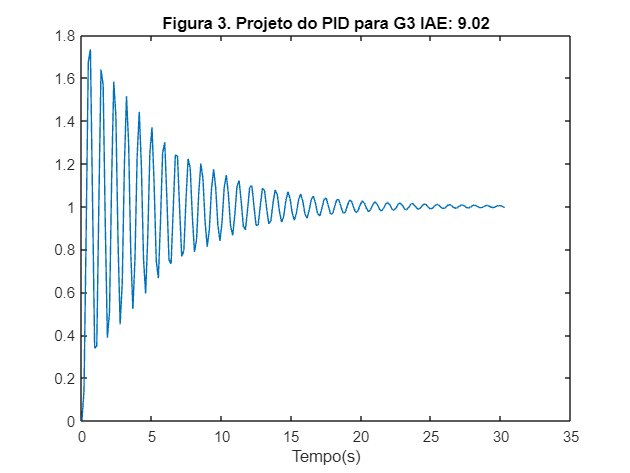

M3=feedback(C3*G3,1);
[y,t]=step(M3);
t=linspace(0,max(t),200);
y=step(M3,t);
plot(t,y);xlabel('Tempo(s)');
iae3=trapz(t,abs(1-y));
ss=sprintf('Figura 3. Projeto do PID para G3 IAE: %3.2f', iae3/iae_G3);
title(ss);

Mas essa resposta apenas com esse PI não conseguiu atender ao quer era pedido:

iae3

iae3 = 3.3046

iae_G3

iae_G3 = 0.3663

Vamos modelar um PD agora para construir o PID:

O objetivo é que o PD retire o UP colocado no PI

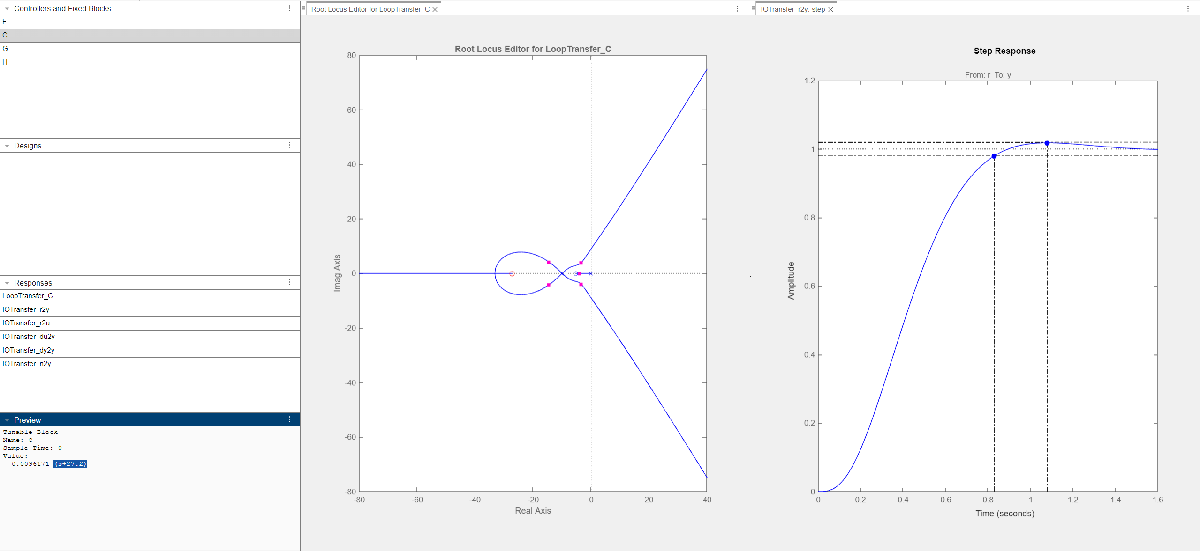

s=tf('s');
G3_polo_zero_zero = G3_polo_zero_ganho*(s+27.2)

G3_polo_zero_zero =
 
       17430 s^2 + 5.656e05 s + 2.489e06
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


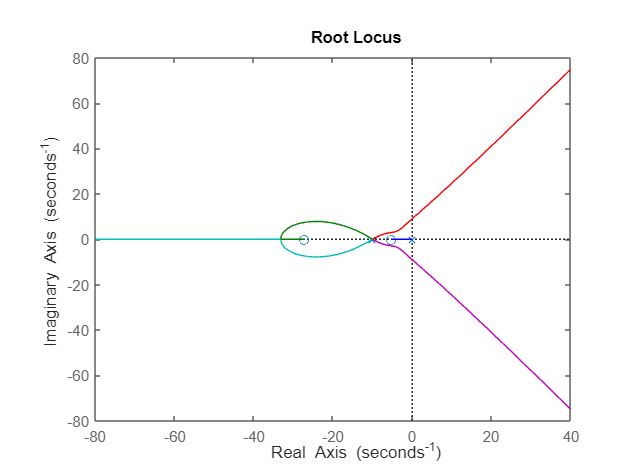

rlocus(G3_polo_zero_zero)

%rltool(G3_polo_zero_ganho)

A resposta possui uma sobressinal de 1.81%, e o seu tempo de estabilização, de aproximadamente 0.83 segundos.

G3_polo_zero_zero_ganho =  0.0096171*G3_polo_zero_zero

G3_polo_zero_zero_ganho =
 
         167.6 s^2 + 5439 s + 2.394e04
  -------------------------------------------
  s^5 + 40 s^4 + 600 s^3 + 4000 s^2 + 10000 s
 
Continuous-time transfer function.
Model Properties


rlocus(G3_polo_zero_zero_ganho)

C3 = (1/s)*(s+5.25)*(s+28.2)*0.0092858*14.525

C3 =
 
  0.1349 s^2 + 4.512 s + 19.97
  ----------------------------
               s
 
Continuous-time transfer function.
Model Properties


Kd = 0.1349

Kd = 0.1349

Kp = 4.512

Kp = 4.5120

Ki = 19.97

Ki = 19.9700

Abaixo a simulação e o cálculo do IAE usando o controlador C3 projetado.

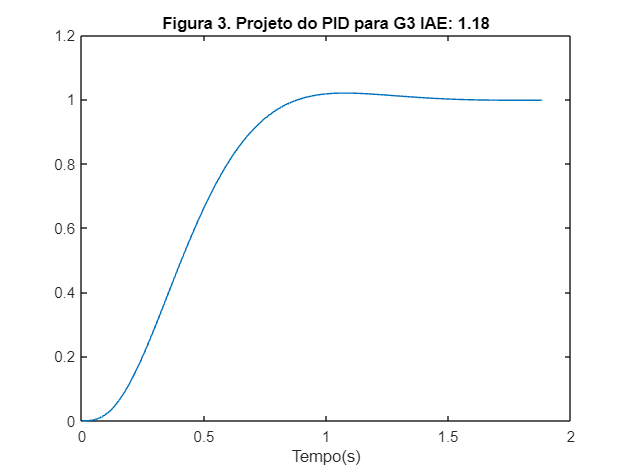

M3=feedback(C3*G3,1);
[y,t]=step(M3);
t=linspace(0,max(t),200);
y=step(M3,t);
plot(t,y);xlabel('Tempo(s)');
iae3=trapz(t,abs(1-y));
ss=sprintf('Figura 3. Projeto do PID para G3 IAE: %3.2f', iae3/iae_G3);
title(ss);

iae3

iae3 = 0.4314

iae_G3

iae_G3 = 0.3663

- **Terceira tentativa de obter o controle:**

Vamos pegar uma refência para usar como base:

G3

G3 =
 
                   1200
  ---------------------------------------
  s^4 + 40 s^3 + 600 s^2 + 4000 s + 10000
 
Continuous-time transfer function.
Model Properties


iae_G3

iae_G3 = 0.3663

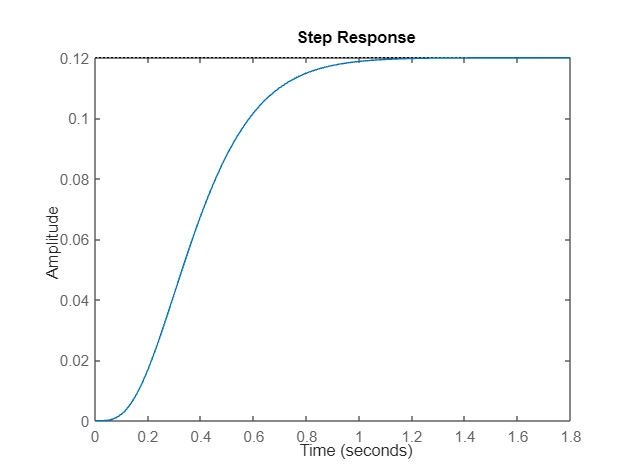

step(G3)

Vamos modelar G3 como sendo um sistema de primeira ordem com tempo morto:

A equação para um sistema de primeira orderm com tempo morto é da seguinte forma:


$$G(s) = \frac{K\cdot e^{-ds}}{\tau s + 1}$$


Em que:

K é o ganho

 $d$ é o tempo morto

 $\tau$ é a constante de tempo 

d1 = 0.08;
k1 = 0.12;
tau1 = 0.42 - d1

tau1 = 0.3400

s=tf('s');

g1 = (k1 * exp(-d1*s))/(tau1*s + 1)

g1 =
 
                    0.12
  exp(-0.08*s) * ----------
                 0.34 s + 1
 
Continuous-time transfer function.
Model Properties


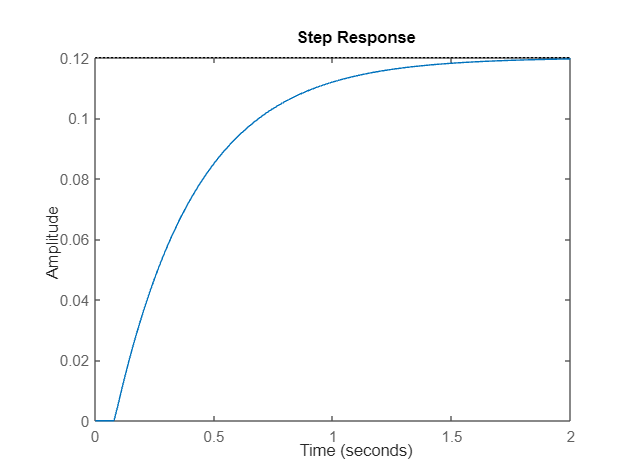

step(g1)

Vamos usar a função pidtuning para gerar um controle inicial:

[C3, iae]=pidtuning(g1,0.34)

C3 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 8.33, Ki = 24.5
 
Continuous-time PI controller in parallel form.
Model Properties


iae = 0.3305

Kp = 8.33

Kp = 8.3300

Ki = 24.5

Ki = 24.5000

Abaixo a simulação e o cálculo do IAE usando o controlador C3 projetado.

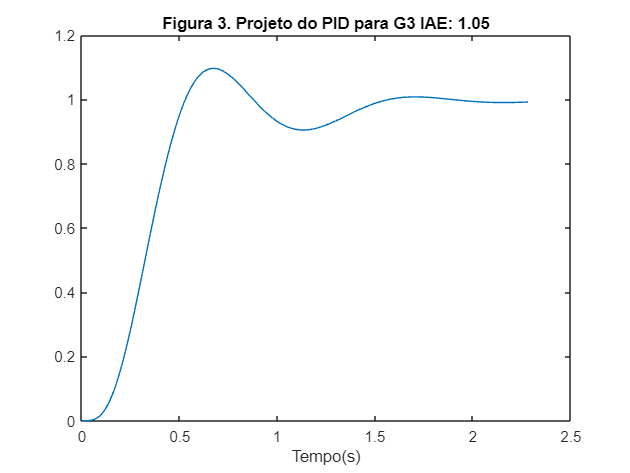

M3=feedback(C3*G3,1);
[y,t]=step(M3);
t=linspace(0,max(t),200);
y=step(M3,t);
plot(t,y);xlabel('Tempo(s)');
iae3=trapz(t,abs(1-y));
ss=sprintf('Figura 3. Projeto do PID para G3 IAE: %3.2f', iae3/iae_G3);
title(ss);

Mas essa resposta apenas com esse PI não conseguiu atender ao quer era pedido:

iae3

iae3 = 0.3847

iae_G3

iae_G3 = 0.3663

Aqui é possível ver que o valor ficou muito próximo do IAE definido como referência.

Com essa aproximação fica mais fácil de variar os ganhos:

A FT do controlador PI é dado por:


$$C(s) = K_p \frac{\left ( s+\frac{K_i}{K_p} \right )}{s}$$


Kp = 8.33- 5

Kp = 3.3300

Ki = 24.5 - 2

Ki = 22.5000

C3 = Kp *((s+(Ki/Kp))/s)

C3 =
 
  3.33 s + 22.5
  -------------
        s
 
Continuous-time transfer function.
Model Properties


Abaixo a simulação e o cálculo do IAE usando o controlador C3 projetado.

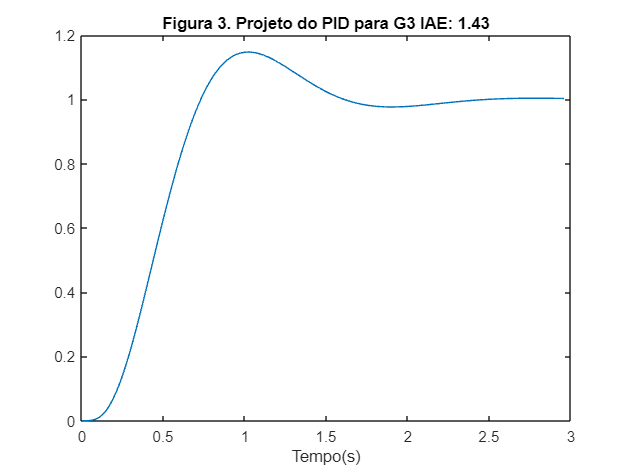

M3=feedback(C3*G3,1);
[y,t]=step(M3);
t=linspace(0,max(t),200);
y=step(M3,t);
plot(t,y);xlabel('Tempo(s)');
iae3=trapz(t,abs(1-y));
ss=sprintf('Figura 3. Projeto do PID para G3 IAE: %3.2f', iae3/iae_G3);
title(ss);